# Intro to Deep Learning and Transfer Learning

This live script will show you how to train a deep learning model using transfer learning to identify playing cards.

We start with some useful concepts on image processing: you can read and show an image in your working folder with this command:

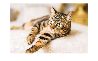

img = imread('cat.jpg');
imshow(img)

We can see the dimension of the image near his name in the workspace. For our deep learning model we will need to resize it:

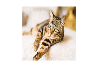

img = imresize(img, [224, 224]);
imshow(img)

Now that we know the basics we can start working on large number of images using image data stores:

imds = imageDatastore('./testDS/','IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\MATLAB intro to Deep Learning\testDS\card\card.jpg';
                              ' ...\MATLAB intro to Deep Learning\testDS\cat\cat.jpg'
                              }
                     Folders: {
                              ' ...\Materiale condiviso con studenti\MATLAB intro to Deep Learning\testDS'
                              }
                      Labels: [card; cat]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


ImageDatastore does not store all the images in the folder in the workspace, it's just a reference. The images will be read one by one when is needed in order to guarantee speed and smart memory use.

You can read an image from a datastore as follows:

img2 = readimage(imds,2);
imshow(img2)

Let's try to classify this image. First we import the net, in our case GoogleNet

net = googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


Then we resize the image:

img2 = imresize(img2, [224, 224]);

And finally, we classify it:

pred = classify(net, img2)

pred = categorical
     tiger cat 


We can also add a second parameter to see the confidence of the results:

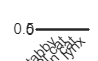

[pred, scores] = classify(net, img2);
highscores = scores > 0.01;
bar(scores(highscores))
categorynames = net.Layers(end).ClassNames;
xticklabels(categorynames(highscores))

if we try the same thing with the card image:

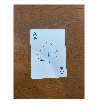

img1 = readimage(imds,1);
imshow(img1)

img1 = imresize(img1, [224,224]);

pred = classify(net, img1)

pred = categorical
     envelope 


As you can see the net failed recognising our card, so we need to retrain it in order to get the accuracy we need.

## Poker Player example

Now we collect the images needed for our test. We will not focus on this code so just run the section and follow the instructions on screen.

NumImages = 100;
suits     = ['D' 'C' 'H' 'S'];
suitsfull = ["Diamond", "Club","Heart",'Spade'];
rank      = ['A' '2' '3' '4' '5' '6' '7' '8' '9' 'T' 'J' 'Q' 'K'];
rankfull  = ["Ace", "Two","Three","Four","Five","Six","Seven","Eight","Nine","Ten","Jack","Queen","King"];

These arrays are used to describe the cards. We are going to capture images from the webcam to create our datastore.

#### If you have errors don't worry and run the checkpoint in the next section to go on

cam = webcam(1);  % in case of multiple webcams use "wecamlist" and change index
preview(cam);
while 1
    cardname = input('Card name in short form:','s');
    if upper(cardname) == 'N'
        break
    elseif ~ischar(cardname) || (numel(cardname) ~= 2) || ~contains(rank,cardname(1)) || ~contains(suits,cardname(2))
        clear cam
        error('Invalid cardname');
    end
    waitBarHandle = waitbar(0,['Prepare ' cardname '... ']);
    cardsDirectory = fullfile(pwd,'cards',cardname);        % fullfile create a string with / as separator
    [~,~] = mkdir(cardsDirectory);
    for i = 1:NumImages
        waitbar(i/NumImages,waitBarHandle,['Saving image: ' num2str(i)]);
        im = snapshot(cam);
       % ---- if you have "Image Processing Toolbox" installed uncomment this
%         if mod(i,2)
%             im = imrotate(im,180);
%         end
% 
%         if mod(i,7) == 5
%             im = imadjust(im,[0 1], [.2 .6]);
%         elseif mod(i,7) == 6
%             im = imadjust(im,[0 1], [.5 1]);
%         end
        imwrite(im,fullfile(cardsDirectory,[cardname,num2str(i) '.png']));

    end
    waitbar(1,waitBarHandle,['Capturing images for ',cardname,' completed.']);
    pause(1)
    close(waitBarHandle);
end

clear cam

Now that we have created a database we can start working on it. 

Let's create an image data store: 

imds = imageDatastore('./cards', 'IncludeSubfolders',true, 'LabelSource','foldernames');

#### If you had errors uncomment and run this section and go on

%imds = imageDatastore("./backup/cards", "IncludeSubfolders", true, "LabelSource","foldernames");

 Split it into Train and Validation:

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.7,'randomized');

In order to use GoogleNet we have to resize our images to 224x224. 

We can do it with imresize() but, for large amount of data, MATLAB implemented augmentedDatastore wich does the work for us:

audsTain = augmentedImageDatastore([224, 224], imdsTrain);
audsValidation = augmentedImageDatastore([224, 224], imdsValidation);

If we want to improve robustness in the model we can add Image Augmenter parameter to perform random opreations on the photos while reading from the datastore

imageAugmenter = imageDataAugmenter(...
    'RandXReflection',1, ...
    'RandYReflection', 1,...
    'RandRotation', [-20,20]);

audsTrain         = augmentedImageDatastore([224, 224],imdsTrain,'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore([224, 224],imdsValidation,'DataAugmentation',imageAugmenter);

Now open the "Deep Network Designer" app app from the apps menu or by typing:

deepNetworkDesigner("-v1")

and follow this instruction:

- Choose GoogleNet and open it

- Zoom into the map and go to the last three layers

- Switch "fully connected layer" with a new one from the left bar

- Click on it and set the OutputSize to the number of type of cards you captured (in the backup case is 52)

- Switch "Classification layer" with a new one from the left bar

- Go to "Data" tab and choose "import Datastore" from the drop down menu

- Choose augmented training -> validation -> import

- Go to "Training" tab and open Training Options

- Set InitialLearnRate to 0.005, ValidationFrequency to 4, MaxEpochs to 6, MiniBatchSize to 64.

- Train the model (this may take some minutes)

- Export the model to the workspace.

#### If you had errors or the training take too much time uncomment and run this section

% load("identifyCards.mat");
% trainedNetwork_1 = netTransfer;

In order to test your model run this section and have fun:

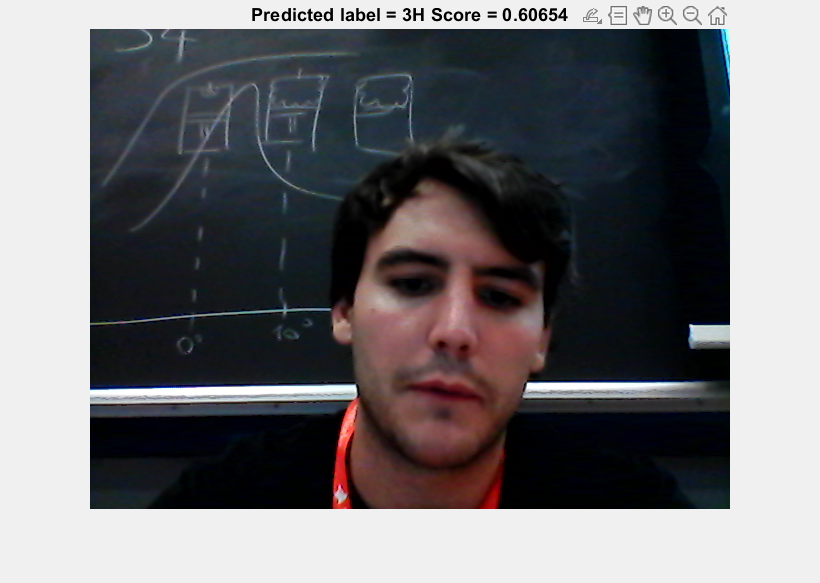

modelName = trainedNetwork_1;  % change the name as the one in your workspace

cam = webcam(1);
fig = figure;
set(gcf,'visible','on')
inputSize = modelName.Layers(1).InputSize;

while 1
    im = snapshot(cam);
    im2 = imresize(im, inputSize(1:2));

    [labelPredicted, scoresPredicted] = classify(modelName,im2);
    output = ['Predicted label = ',char(labelPredicted),' Score = ',num2str(max(scoresPredicted))];
    imshow(im);
    hold on
    title(output)
    hold off
    pause(0.05)

    if ~ishandle(fig)
        break
    end
end

clear cam

*Copyright 2021 The MathWorks, Inc.*